# 'coneplot' method usage example

Common setup for all examples

ex_setup

Setup complete


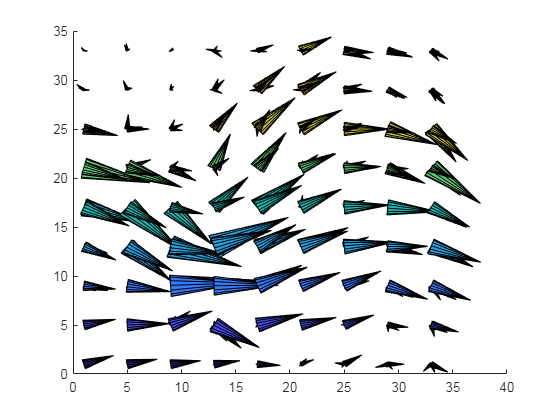

% Start timer

tic
% Create povlab object
pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

% Create scene
pl.scene_begin('scene_file', 'coneplot.pov', 'image_file', 'coneplot.png');
pl.include("shapes");
pl.include("textures");
pl.include("glass");
pl.include("golds");

pl.global_settings("assumed_gamma 1");

% Camera
pl.camera('angle', 50, 'location', [30 50 15], 'look_at', [9 0 1]);

% Lights
pl.light('location', [40 80 30],  'color', [2 2 2], 'shadowless', true);
pl.light('location', [0 0 0],     'color', [40 60 20], 'shadowless', true);

% Bounding box
tex =  pl.declare("tex_green", pl.texture('base', 'Silver1', 'pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.1 0.3 0],   'finish', "phong 1 reflection {0.3 metallic 0.8}"));
pl.wire_box('llf_corner', [0 0 0], 'urb_corner', [35 41 15], 'radius', 0.1, 'texture', tex);

% Wind for streams
load wind u v w x y z
[m,n,p] = size(u);
m = 35;
n = 41;
p = 15;
[~,n,p] = size(u);

% Coneplot
[Cx, Cy, Cz] = meshgrid(1:4:m,1:4:n,1:4:p);
cp = coneplot(u,v,w,Cx,Cy,Cz,y,5);

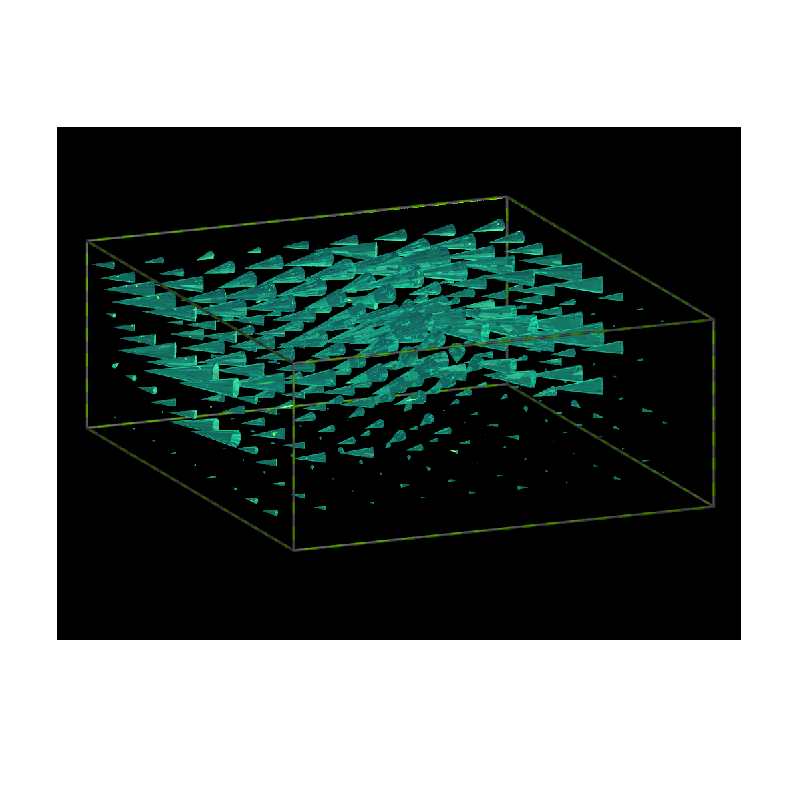

pl.coneplot('data', cp);

pl.scene_end();

img = pl.render();
imshow(img);

% Elapsed time

toc

Elapsed time is 8.229965 seconds.
